# Problem 1

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
Re = 6378.1;
mu = 398600.4415;

Given:

r1 = 2*Re, r2 = 4*Re

r1 = 1.2756e+04

r2 = 2.5512e+04

## Part a)

aT = 1/2 * (r1 + r2)

aT = 1.9134e+04

v1 = sqrt(mu/r1)

v1 = 5.5900

v1_n = sqrt(mu*(2/r1-1/aT))

v1_n = 6.4547

v2_0 = sqrt(mu*(2/r2-1/aT))

v2_0 = 3.2274

v2 = sqrt(mu/r2)

v2 = 3.9527

dv1 = v1_n - v1

dv1 = 0.8648

dv2 = v2 - v2_0

dv2 = 0.7253

dvtot = dv1 + dv1

dvtot = 1.7295

n = sqrt(mu/aT^3)

n = 2.3853e-04

TOF = 2*pi/n, TOF_hr = TOF/3600

TOF = 2.6341e+04

TOF_hr = 7.3169

n2 = sqrt(mu/r2^3);
TA = pi;
phase = TA-n2*TOF, phase_deg = rad2deg(phase)

phase = -0.9395

phase_deg = -53.8269

ts = 2*pi/(n-n2), ts_hr = ts/3600

ts = 7.5156e+04

ts_hr = 20.8768

## Part b)

TA_deg = 270; TA = deg2rad(TA_deg)

TA = 4.7124

inangle = 2*pi - TA

inangle = 1.5708

c = sqrt(r1^2 + r2^2 - 2*r1*r2*cos(TA))

c = 2.8524e+04

s = (r1+r2+c)/2

s = 3.3396e+04

amin = s/2

amin = 1.6698e+04

P1Fmin = 2*amin - r1

P1Fmin = 2.0640e+04

P2Fmin = 2*amin - r2

P2Fmin = 7.8838e+03

energymin = -mu/2/amin

energymin = -11.9355

zeta = asin(r1/c*sin(inangle))

zeta = 0.4636

emin = sqrt(r2^2+P2Fmin^2-2*r2*P2Fmin*cos(zeta))/2/amin

emin = 0.5628

vD = sqrt(mu*(2/r1-1/amin))

vD = 6.2148

vA = sqrt(mu*(2/r2-1/amin))

vA = 2.7160

pmin = amin*(1-emin^2)

pmin = 1.1409e+04

tsD = -acos(1/emin * (pmin/r1 - 1)), tsd_deg = rad2deg(tsD)

tsD = -1.7595

tsd_deg = -100.8123

tsA = tsD+TA, tsa_deg = rad2deg(tsA)

tsA = 2.9529

tsa_deg = 169.1877

hmin = sqrt(mu*pmin)

hmin = 6.7438e+04

gammaDmin = -acos(hmin/r1/vD), gammaDmin_deg = rad2deg(gammaDmin)

gammaDmin = -0.5536

gammaDmin_deg = -31.7175

gammaAmin = acos(hmin/r2/vA), gammaAmin_deg = rad2deg(gammaAmin)

gammaAmin = 0.2318

gammaAmin_deg = 13.2825

dvD = sqrt(v1^2 + vD^2 - 2*v1*vD*cos(gammaDmin))

dvD = 3.2814

dvA = sqrt(v2^2 + vA^2 - 2*v2*vA*cos(gammaAmin))

dvA = 1.4505

betaD = asin(vD/dvD * -sin(gammaDmin)), betaD_deg = rad2deg(betaD)

betaD = 1.4782

betaD_deg = 84.6965

alphaD = pi-abs(betaD), alphaD_deg = rad2deg(alphaD)

alphaD = 1.6634

alphaD_deg = 95.3035

betaA = pi- asin(v2/dvA * sin(gammaAmin))

betaA = 2.4650

alphaA = pi-abs(betaA), alphaA_deg = rad2deg(alphaA)

alphaA = 0.6766

alphaA_deg = 38.7636

iCr1 = [cos(0),-sin(0);sin(0) cos(0)];
iCr2 = [cos(tsA-tsD), -sin(tsA-tsD); sin(tsA-tsD) cos(tsA-tsD)];
dvtot = dvD+dvA

dvtot = 4.7318

plotorbit(r1,0,0,2*pi,0,'')
hold on
plotorbit(r2,0,0,2*pi,0,'')
plotorbit(Re,0,0,2*pi,0,'g')
plotpos(r1,0,0,'r',0,1)
plotpos(r2,0,7*pi/2,'r',0,1)
plotorbit(amin,emin,tsD,tsA,tsD,'g')
TOF = 1.0723e4;
n2 = sqrt(mu/r2^3);
phase = TA-n2*TOF, phase_deg = rad2deg(phase)

phase = 3.0511

phase_deg = 174.8123

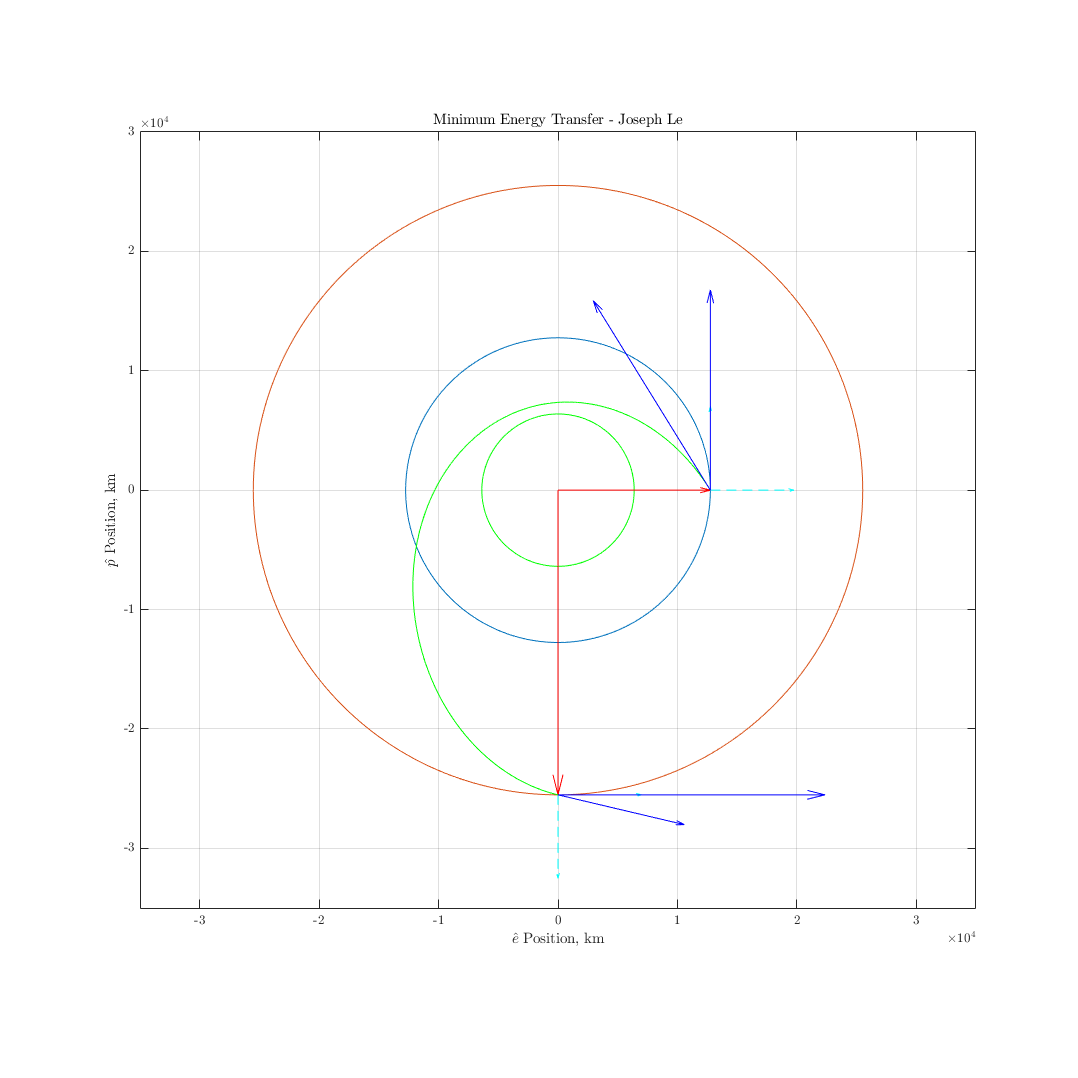

plotvel(r1,0,0,v1*iCr1*[sin(0);cos(0)],'b',0,0,3e3)
plotvel(amin,emin,tsD,vD*iCr1*[sin(gammaDmin);cos(gammaDmin)],'b',0,tsD,3e3)
plotvel(r2,0,deg2rad(270),v1*iCr2*[sin(0);cos(0)],'b',0,0,4e3)
plotvel(amin,emin,tsA,vA*iCr2*[sin(gammaAmin);cos(gammaAmin)],'b',0,tsD,4e3)

xlim([-3.5 3.5]*1e4)
ylim([-3.5 3]*1e4)
xlabel('$\hat{e}$ Position, km')
ylabel('$\hat{p}$ Position, km')
title('Minimum Energy Transfer - Joseph Le')
set(gcf,'position',[0,0,1500,1500])
hold off

## Part c)

TOF_hr = 6.25, TOF = TOF_hr * 3600

TOF_hr = 6.2500

TOF = 22500

amin

amin = 1.6698e+04

TOFpar = 1/3 * sqrt(2/mu)*(s^(3/2)+(s-c)^(3/2))

TOFpar = 4.8109e+03

[a,alpha,beta] = bisection(TOF,amin,c,mu,'2B',.001)

a = 2.0449e+04

alpha = 4.0268

beta = -0.7048

alpha_deg = rad2deg(alpha), beta_deg = rad2deg(beta)

alpha_deg = 230.7187

beta_deg = -40.3831

p = 4*a*(s-r1)*(s-r2)/c^2 * sin((alpha+beta)/2)^2

p = 1.6227e+04

e = sqrt(1-p/a)

e = 0.4544

rD = r1, rA = r2

rD = 1.2756e+04

rA = 2.5512e+04

vD = sqrt(mu*(2/rD - 1/a))

vD = 6.5577

vA = sqrt(mu*(2/rA - 1/a))

vA = 3.4286


rp = a*(1-e)

rp = 1.1157e+04

ra = a*(1+e)

ra = 2.9742e+04


tsD = -acos(1/e * (p/r1 - 1)), tsD_deg = rad2deg(tsD)

tsD = -0.9289

tsD_deg = -53.2229

tsA = tsD+TA, tsA_deg = rad2deg(tsA)

tsA = 3.7835

tsA_deg = 216.7771


h = sqrt(mu*p)

h = 8.0424e+04

gammaD = -acos(h/r1/vD), gammaD_deg = rad2deg(gammaD)

gammaD = -0.2787

gammaD_deg = -15.9673

gammaA = -acos(h/r2/vA), gammaA_deg = rad2deg(gammaA)

gammaA = -0.4042

gammaA_deg = -23.1586



dvD = sqrt(v1^2 + vD^2 - 2*v1*vD*cos(gammaD))

dvD = 1.9404

dvA = sqrt(v2^2 + vA^2 - 2*v2*vA*cos(gammaA))

dvA = 1.5680

dvtot = dvD+dvA

dvtot = 3.5084

betaD =asin(vD/dvD * sin(gammaD)), betaD_deg = rad2deg(betaD)

betaD = -1.1936

betaD_deg = -68.3869

alphaD = pi-abs(betaD), alphaD_deg = rad2deg(alphaD)

alphaD = 1.9480

alphaD_deg = 111.6131

betaA = pi- asin(v2_n/dvA * sin(gammaAmin))

betaA = 2.5239

alphaA = pi- abs(betaA), alphaA_deg = rad2deg(alphaA)

alphaA = 0.6177

alphaA_deg = 35.3913

iCr1 = [cos(0),-sin(0);sin(0) cos(0)];
iCr2 = [cos(tsA-tsD), -sin(tsA-tsD); sin(tsA-tsD) cos(tsA-tsD)];

phase = TA-n2*TOF, phase_deg = rad2deg(phase)

phase = 1.2264

phase_deg = 70.2683

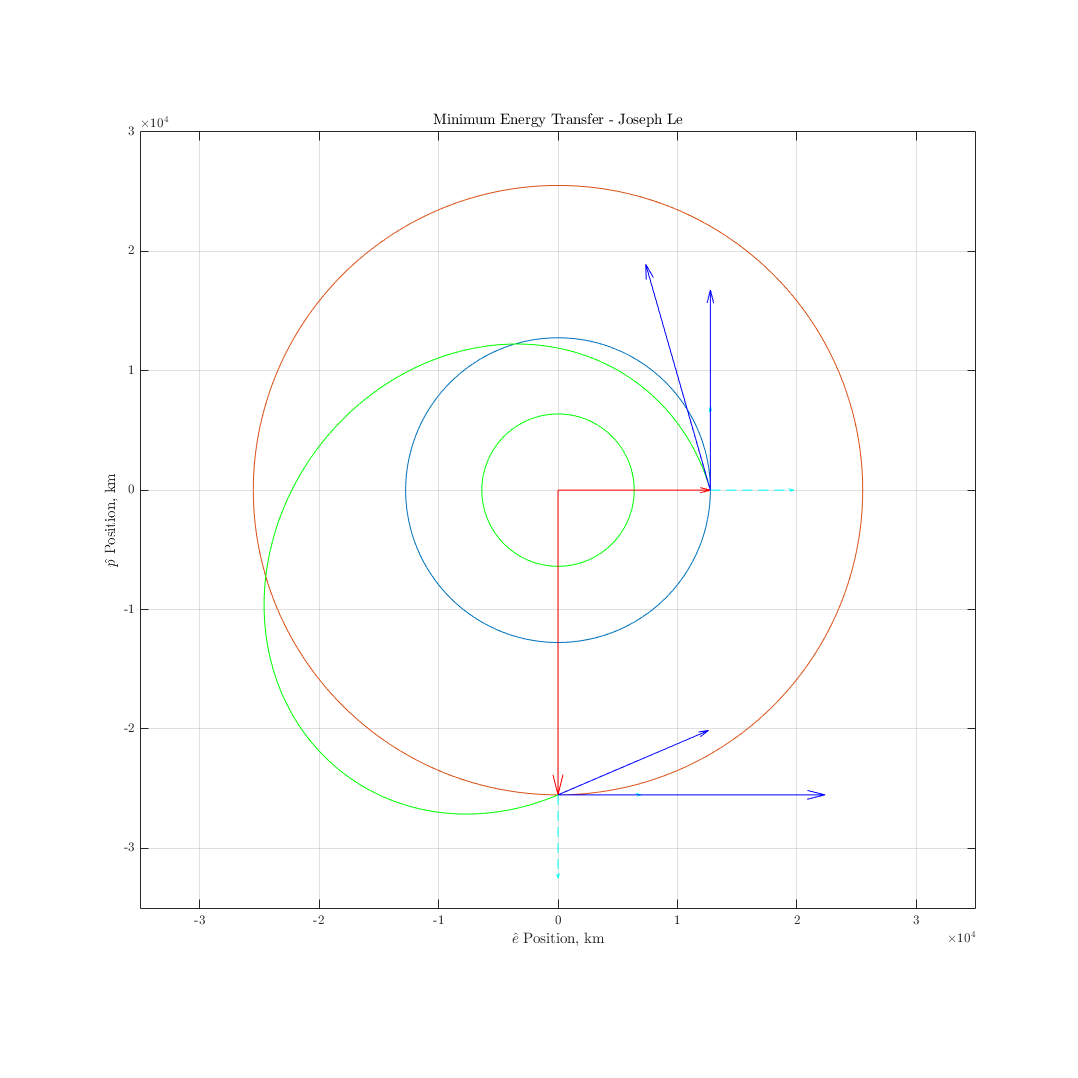



plotorbit(r1,0,0,2*pi,0,'') % orbit 1
hold on
plotorbit(r2,0,0,2*pi,0,'') % orbit 2
plotorbit(Re,0,0,2*pi,0,'g') % Earth
plotpos(r1,0,0,'r',0,1) % position 1,D
plotpos(r2,0,7*pi/2,'r',0,1) % position 2,A
plotorbit(a,e,tsD,tsA,tsD,'g')

plotvel(r1,0,0,v1*iCr1*[sin(0);cos(0)],'b',0,0,3e3) % circlular velocity at 1
plotvel(a,e,tsD,vD*iCr1*[sin(gammaD);cos(gammaD)],'b',0,tsD,3e3) % departure velocity
plotvel(r2,0,deg2rad(270),v1*iCr2*[sin(0);cos(0)],'b',0,0,4e3) % circular velocity at 2
plotvel(a,e,tsA,vA*iCr2*[sin(gammaA);cos(gammaA)],'b',0,tsD,4e3) % arrival velocity

xlim([-3.5 3.5]*1e4)
ylim([-3.5 3]*1e4)
xlabel('$\hat{e}$ Position, km')
ylabel('$\hat{p}$ Position, km')
title('Minimum Energy Transfer - Joseph Le')

set(gcf,'position',[0,0,1500,1500])

function [a,alpha,beta] = bisectionSMA(TOF,amin,c,mu,type,tol)
s = amin*2;
if type(2) == 'A' | type(2) == 'B'
    amax = 100*amin;
elseif type(2) == 'H'
    amax = -100*amin;
    amin = 0;
end

TOFtest = TOF + 100000;
% for i = 1:10
while ~(abs(TOF - TOFtest) < tol)
    aguess = (amax+amin)/2;
    if isequal(type,'1A')
        alpha = 2*asin(sqrt(s/2/aguess));
        beta = 2*asin(sqrt((s-c)/2/aguess));
        TOFtest = sqrt(aguess^3/mu) * ((alpha - beta) - (sin(alpha) - sin(beta)));
    elseif isequal(type,'1B')
        alpha = 2*pi-2*asin(sqrt(s/2/aguess));
        beta = 2*asin(sqrt((s-c)/2/aguess));
        TOFtest = sqrt(aguess^3/mu) * ((alpha - beta) - (sin(alpha) - sin(beta)));
    elseif isequal(type,'2A')
        alpha = 2*asin(sqrt(s/2/aguess));
        beta = -2*asin(sqrt((s-c)/2/aguess));
        TOFtest = sqrt(aguess^3/mu) * ((alpha - beta) - (sin(alpha) - sin(beta)));
    elseif isequal(type,'2B')
        alpha = 2*pi-2*asin(sqrt(s/2/aguess));
        beta = -2*asin(sqrt((s-c)/2/aguess));
        TOFtest = sqrt(aguess^3/mu) * ((alpha - beta) - (sin(alpha) - sin(beta)));
    elseif isequal(type,'1H')
        alphap = 2*asinh(sqrt(s/2/abs(aguess)));
        betap = 2*asinh(sqrt((s-c)/2/abs(aguess)));
        TOFtest = sqrt(abs(aguess)^3/mu)*((sinh(alphap)-alphap)-(sinh(betap)-betap));
    elseif isequal(type,'2H')
        alphap = 2*asinh(sqrt(s/2/abs(aguess)));
        betap = -2*asinh(sqrt((s-c)/2/abs(aguess)));
        TOFtest = sqrt(abs(aguess)^3/mu)*((sinh(alphap)-alphap)-(sinh(betap)-betap));
    end
    
    if type(2) == 'A' 
        if TOFtest > TOF
            amin = aguess;
        elseif TOFtest < TOF
            amax = aguess;
        else
            break
        end        
    elseif type(2) == 'H'| type(2) == 'B'
        if TOFtest < TOF
            amin = aguess;
        elseif TOFtest > TOF
            amax = aguess;
        else
            break
        end
        
    end
    
end
a = aguess;
end